k_e = 0.3824

k_e = 0.3824

k_m = 0.3824

k_m = 0.3824

J = 0.0019

J = 0.0019

R = 4.6296

R = 4.6296


t = linspace(0, 0.5);

y_sr = (1 / k_e) * (1 - exp(- (k_e * k_m) / (R * J) * t))

y_sr =          0    0.2106    0.4042    0.5823    0.7460    0.8965    1.0349    1.1622    1.2792    1.3867    1.4857    1.5766    1.6602    1.7371    1.8078    1.8728    1.9326    1.9876    2.0381    2.0846    2.1273    2.1666    2.2027    2.2359    2.2664    2.2945    2.3203    2.3441    2.3659    2.3860    2.4044    2.4214    2.4370    2.4513    2.4645    2.4766    2.4878    2.4980    2.5074    2.5161    2.5241    2.5314    2.5381    2.5443    2.5500    2.5553    2.5601    2.5645    2.5686    2.5723



y_c = sign(t + 0.1) / k_e

y_c =     2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151



num_s = [k_m / R];
den_s = [J, k_m * k_e / R, 0];
sys_s = tf(num_s, den_s);

%plot(t, y_c, 'r--', LineWidth=1)
%{
plot(t, y_sr, 'c', LineWidth=1.5)
hold on
impulse(sys_s, 'k--')
legend('y_{s.r.} - аналитика', 'y_{s.r.} - симуляция')
title('Переходная функция для ДПТ')
grid()
ylabel("f(t)")
xlabel('t')
hold off
%}



num_i = [k_m / R];
den_i = [J, k_m * k_e / R];
sys_i = tf(num_i, den_i);

y_ir = (k_m / (R * J)) * exp(- (k_e * k_m) / (R * J) * t)

y_ir =    43.4731   39.9721   36.7531   33.7933   31.0718   28.5696   26.2688   24.1533   22.2082   20.4197   18.7753   17.2633   15.8730   14.5947   13.4194   12.3387   11.3450   10.4314    9.5913    8.8189    8.1087    7.4557    6.8553    6.3032    5.7956    5.3289    4.8997    4.5051    4.1423    3.8087    3.5020    3.2200    2.9607    2.7222    2.5030    2.3014    2.1161    1.9457    1.7890    1.6449    1.5125    1.3907    1.2787    1.1757    1.0810    0.9940    0.9139    0.8403    0.7726    0.7104


%{
plot(t, y_ir, 'c', LineWidth=1.5)
hold on
impulse(sys_i, 'k--')
legend('y_{i.r.} - аналитика', 'y_{i.r.} - симуляция')
title('Весовая функция для ДПТ')
grid()
ylabel("f(t)")
xlabel('t')
hold off
%}

w = linspace(0, 200)

w =          0    2.0202    4.0404    6.0606    8.0808   10.1010   12.1212   14.1414   16.1616   18.1818   20.2020   22.2222   24.2424   26.2626   28.2828   30.3030   32.3232   34.3434   36.3636   38.3838   40.4040   42.4242   44.4444   46.4646   48.4848   50.5051   52.5253   54.5455   56.5657   58.5859   60.6061   62.6263   64.6465   66.6667   68.6869   70.7071   72.7273   74.7475   76.7677   78.7879   80.8081   82.8283   84.8485   86.8687   88.8889   90.9091   92.9293   94.9495   96.9697   98.9899


%{
%A = k_m ./ sqrt((k_m * k_e) * (k_m * k_e)  + (J * R .* w ) .* (J * R .* w ) )
T_s = (J * R) / (km * ke);
A = (1 / k_e) ./ sqrt(1 + w.^2 * T_s^2)
phi = atan(- (w * R * J) / (k_e * k_m)) * 180 / pi
figure('Position', [1000 0 800 450])
%bode(sys_s)
lafc = 20 * log10(A)

figure;
subplot(2,1,1);
%plot(w, lafc, 'c', LineWidth=1.5)
semilogx(w, lafc)
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('ЛАЧХ для ДПТ');
grid on

subplot(2,1,2)
%plot(w, phi, 'c', LineWidth=1.5)
phi1 = atan2(-w * T_s * (1 / k_e)./(1+w.^2 * T_s^2), (1 / k_e)./(1+w.^2 * T_s^2));
semilogx(w, 20 * log10(phi1))
xlabel('Frequency (rad/s)');
ylabel('Phase (degrees)');
title('ЛФЧХ для ДПТ');
xlim([0 1000])
grid on;
hold off

figure('Position', [1000 0 800 450])
ops = bodeoptions;
ops.Title.String = 'ЛАФЧХ'
ops.Title.FontSize = 15
ops.XLabel.FontSize = 12
ops.YLabel.FontSize = 12
   
h = bodeplot(sys_s, 'c', ops)
grid on;
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

%ax = findall(gcf,'type','axes');
%legend(ax(2),'ЛАЧХ');
%legend(ax(3),'ЛФЧХ');
%legend('ЛАЧХ','ЛФЧХ');
%}
%{

T_s = (J * R) / (k_m * k_e);

phi1 = atan2(-w * T_s * (1 / k_e)./(1+w.^2 * T_s^2), (1 / k_e)./(1+w.^2 * T_s^2)) * 180 / pi;




figure('Position', [1000 0 800 450])

plot(w, phi1, 'LineWidth', 1.5, 'DisplayName', 'ФЧХ')
%figure('Position', [1000 0 800 450])
%plot(t, y_sr, 'LineWidth', 1.5)

%plot(t, y_ir, 'LineWidth', 1.5)


%ezplot('(0.3824 / sqrt( 0.3824 * 0.3824 * 0.3824 * 0.3824 + (0.0019 * 4.6296 * x ) * (0.0019 * 4.6296 * x ))) ', [0 200])
%fp = fplot(@(x) (0.3824 / sqrt( 0.3824 * 0.3824 * 0.3824 * 0.3824 + (0.0019 * 4.6296 * x ) * (0.0019 * 4.6296 * x ))),[0 200] )
%fp.LineStyle = '-'
%fp.LineWidth = 1.5
%axis tight
%ylim([0 2.7])

%yline(1 / k_e, '-.')

%grid()
%title('Амплитудно-частотная характеристика')
title('Фазово-частотная характеристика')
%title('Переходная функция для ДПТ')
%legend('y_{s.r.}', '1 / k_e')
%ylabel("f(t)")
%xlabel('t, s')

%title('Весовая функция для ДПТ')
%legend('y_{i.r.}')
%ylabel("f(t)")
%xlabel('t, s')

legend()
%ylabel("A")
ylabel('φ, degrees')
xlabel('ω, rad / s')
grid("on")
%}



figure('Position', [1000 0 800 450])
ops = bodeoptions;
ops.Title.String = 'ЛАФЧХ'

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.Title.FontSize = 15

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.XLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.YLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

   
h = bodeplot(sys_i, 'c', ops)


h =

	resppack.bodeplot



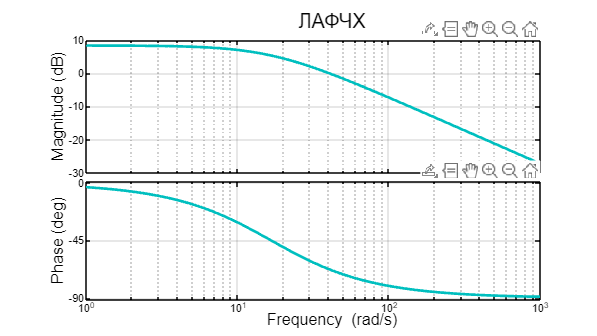

grid on;
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth



%{
w = linspace(0, 500)
phi1 = atan2(-w * T_s * (1 / k_e)./(1+w.^2 * T_s^2), (1 / k_e)./(1+w.^2 * T_s^2)) * 180 / pi;

plot(w, phi1)
%}

